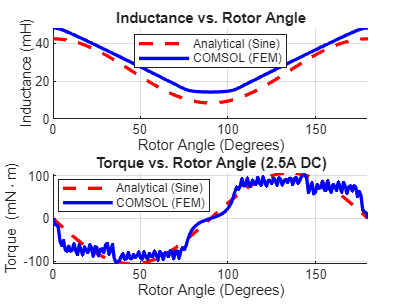

% MATLAB Code for Analytical vs. COMSOL Comparison
clear; clc; close all;

%% 1. Analytical Setup
theta_deg = 0:1:180; % Plotting half a rotation to match your COMSOL sweep
theta_rad = deg2rad(theta_deg);

% Analytical Parameters (from our corrected calculations)
L_max_ana = 42.4;  % mH
L_min_ana = 8.48;  % mH
I = 2.5;           % Amps

L_0 = (L_max_ana + L_min_ana) / 2;
L_2 = (L_max_ana - L_min_ana) / 2;

% Analytical Equations
L_ana = L_0 + L_2 * cos(2 * theta_rad); % in mH
T_ana = -(I^2) * (L_2 / 1000) * sin(2 * theta_rad) * 1000; % converted to mN*m

%% 2. Load COMSOL Data
% NOTE: Ensure these files are in the same folder as your script.
% COMSOL exports often have text headers. 'readmatrix' usually skips them automatically.
try
    data_L = readmatrix('inductance.csv');
    theta_comsol_L = data_L(:, 1);
    L_comsol = data_L(:, 2) * 1000; % Convert H to mH
    
    data_T = readmatrix('torque.csv');
    theta_comsol_T = data_T(:, 1);
    T_comsol = data_T(:, 2); % Assuming you exported in mN*m. If exported in Nm, multiply by 1000.
catch
    warning('COMSOL CSV files not found. Only plotting analytical data.');
    theta_comsol_L = []; L_comsol = [];
    theta_comsol_T = []; T_comsol = [];
end

%% 3. Plotting
figure('Name', 'Analytical vs FEM Comparison', 'Color', 'w', 'Position', [100, 100, 800, 600]);

% Inductance Plot
subplot(2,1,1);
hold on; grid on;
plot(theta_deg, L_ana, '--r', 'LineWidth', 2, 'DisplayName', 'Analytical (Sine)');
if ~isempty(L_comsol)
    plot(theta_comsol_L, L_comsol, '-b', 'LineWidth', 2, 'DisplayName', 'COMSOL (FEM)');
end
title('Inductance vs. Rotor Angle');
xlabel('Rotor Angle (Degrees)');
ylabel('Inductance (mH)');
legend('Location', 'best');
xlim([0 180]);

% Torque Plot
subplot(2,1,2);
hold on; grid on;
plot(theta_deg, T_ana, '--r', 'LineWidth', 2, 'DisplayName', 'Analytical (Sine)');
if ~isempty(T_comsol)
    plot(theta_comsol_T, T_comsol, '-b', 'LineWidth', 2, 'DisplayName', 'COMSOL (FEM)');
end
title('Torque vs. Rotor Angle (2.5A DC)');
xlabel('Rotor Angle (Degrees)');
ylabel('Torque (mN\cdotm)');
legend('Location', 'best');
xlim([0 180]);